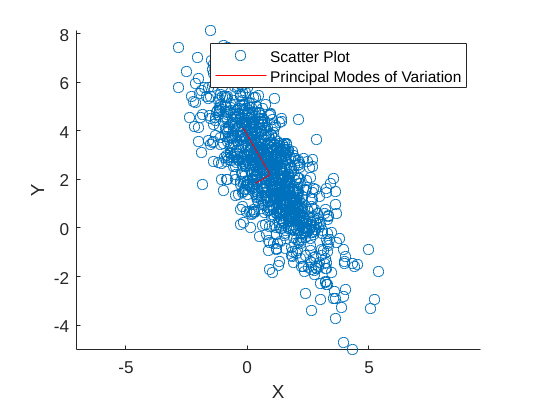

% Title
% Principal Mode of Variation of Multivariate Gaussian

% Declaring Variables
N = [10,100,1000,10000,100000];
u = [1;2];
C = [1.6250,-1.9486;-1.9486,3.8750];
% lower triangular cholesky decomposition
A = transpose(cholesky(C));

% Seed
rng(1);

% Logic
% X = Aw + u
% sorting eigenvalues of C in descending order
% taking pair (value and vector) corresponding to largest eigenvalue

% Working
[V,D] = eig(C);
[d,index] = sort(diag(D),'descend');
Dsort = D(index,index);
Vsort = V(:,index);
% empirical eigenvalue and eigenvector
empeigval1 = Dsort(1,1);
empeigvec1 = Vsort(:,1);
empeigval2 = Dsort(2,2);
empeigvec2 = Vsort(:,2);
% empirical mean
empmean = zeros(2,1);

sample = 3;
X = zeros(2,N(sample));
B = A * randn(2,N(sample));
for j = 1:2
  for i = 1:N(sample)
   X(j,i) = B(j,i) + u(j);
  end
  empmean(j,1) = sum(X(j,:)) / N(sample); % MLE for Mean
end

% finding end points for principal mode of variation
pmvend1 = empmean + sqrt(empeigval1) * (empeigvec1 / sqrt(empeigvec1(1)^2 + empeigvec1(2)^2));
xpoints1 = [empmean(1),pmvend1(1)];
ypoints1 = [empmean(2),pmvend1(2)];
pmvend2 = empmean + sqrt(empeigval2) * (empeigvec2 / sqrt(empeigvec2(1)^2 + empeigvec2(2)^2));
xpoints2 = [empmean(1),pmvend2(1)];
ypoints2 = [empmean(2),pmvend2(2)];

% Plotting
scatter(X(1,:),X(2,:),color = 'blue');
axis equal;
hold on;
% plotting the line
plot(xpoints1,ypoints1, color = 'red');
plot(xpoints2,ypoints2, color = 'red');
legend('Scatter Plot','Principal Modes of Variation');
xlabel('X');
ylabel('Y');


% Cholesky Decomposition
% solves A * A' = C
% https://in.mathworks.com/matlabcentral/answers/482145-cholesky-decomposition-column-wise-algorithm-implementation

function A = cholesky(C)
  [n,~] = size(C);
  A = zeros(n,n);
  for j = 1:n
    for i = 1:j-1
      sum1 = 0;
      for k = 1:i-1
        sum1 = sum1 + A(k,i) * A(k,j);
      end
      A(i,j) = (C(i,j) - sum1) / A(i,i);
    end
    sum2 = 0;
    for k = 1:j-1 
      sum2 = sum2 + A(k,j) * A(k,j);
    end
    A(j,j) = sqrt(C(j,j) - sum2);
  end
end